Image 1


bbox =      7     9    22     5
     5    10    24     6
     3     8    27     6


Num bbox: 3


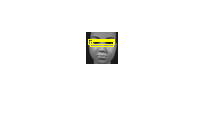

Image 2


bbox =      5    10    24     6


Num bbox: 1


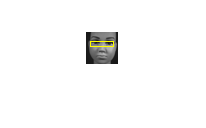

Image 3


bbox =      5    10    24     6
     3     8    27     6


Num bbox: 2


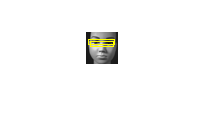

Image 4


bbox =      5     8    24     6
     5    10    24     6
     3     8    27     6


Num bbox: 3


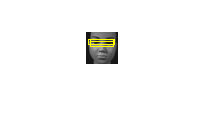

Image 5


bbox =      5    10    24     6
     3     8    27     6


Num bbox: 2


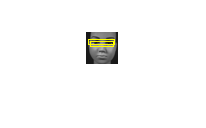

Image 6


bbox =      5    10    24     6
     3     8    27     6


Num bbox: 2


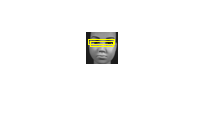

Image 7


bbox =      7     9    22     5
     5    10    24     6
     3     8    27     6


Num bbox: 3


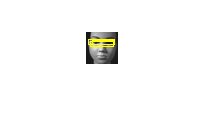

Image 8


bbox =      5     8    24     6
     5    10    24     6
     3     8    27     6


Num bbox: 3


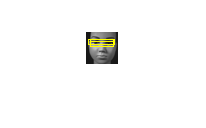

Image 9


bbox =      7     9    22     5
     5    10    24     6
     3     8    27     6


Num bbox: 3


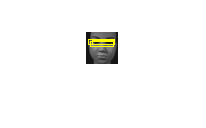

Image 10


bbox =      5    10    24     6


Num bbox: 1


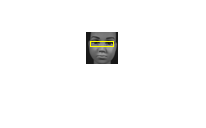

Image 11


bbox =      5    10    24     6


Num bbox: 1


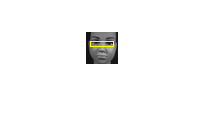

Image 12


bbox =      7     3    22     5


Num bbox: 1


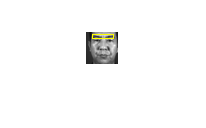

Image 13


bbox =      7     9    22     5
     5     5    24     6
     5    10    24     6


Num bbox: 3


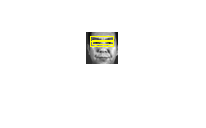

Image 14


bbox =      7     7    22     5
     5     8    24     6


Num bbox: 2


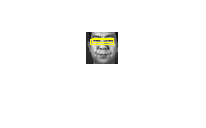

Image 15


bbox =      7     3    22     5
     7     7    22     5


Num bbox: 2


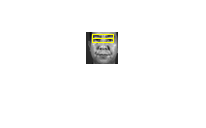

Image 16


bbox =      3     8    24     6


Num bbox: 1


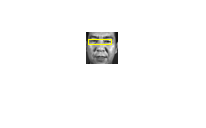

Image 17


bbox =      9     9    22     5


Num bbox: 1


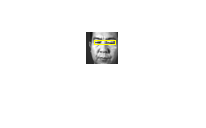

Image 18


bbox =      8    10    24     6


Num bbox: 1


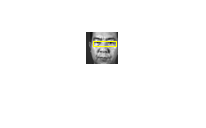

Image 19


bbox =      7     9    22     5


Num bbox: 1


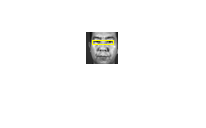

Image 20


bbox =      5     7    22     5
     3     6    27     6


Num bbox: 2


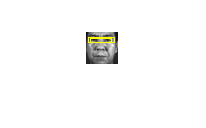

Image 21


bbox =      7     7    22     5
     5     5    24     6


Num bbox: 2


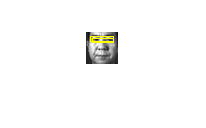

Image 22


bbox =      7     9    22     5
     5     5    24     6
     5    10    24     6


Num bbox: 3


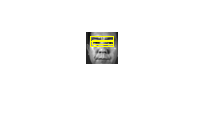

foldername = "data/database0/testing_set/testing";
orig = cell(1, 22);
detector = vision.CascadeObjectDetector('EyePairSmall');
detector.MergeThreshold = 0;    % One undetected at threshold 1, more when higher
for i=1:22
    filename = sprintf("%s%i%s", foldername, i, ".bmp");
    orig{i} = imread(filename);
    disp("Image " + i)
    bbox = detector(orig{i})
    [m, n] = size(bbox);
    if isempty(bbox)
        disp("ERROR: No eye detected")
    else
        disp("Num bbox: " + m)
        out = insertObjectAnnotation(orig{i}, 'rectangle', bbox, '');
        figure;
        imshow(out)
        drawnow;
    end
end

% bbox = detector(orig{1})
% bbox = step(detector, orig{1})
% bbox = detector(imread("data/database0/testing_set/testing1.bmp"))